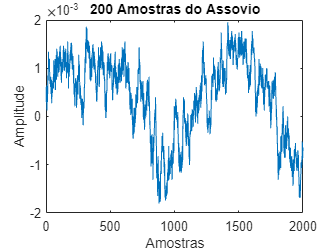

% Ler o arquivo WAV
[audio1, samplerate] = audioread('Assovio.wav');
[audio2, samplerate] = audioread('Testando123.wav');

% Exibir a taxa de amostragem e as dimensões dos dados
samplerate;
size(audio1);
size(audio2);

% Reproduzir o áudio
%sound(audio1, samplerate);
%sound(audio2, samplerate);

%1)
%a) 
plot(audio1(7001:9000));
title('200 Amostras do Assovio');
xlabel('Amostras');
ylabel('Amplitude');

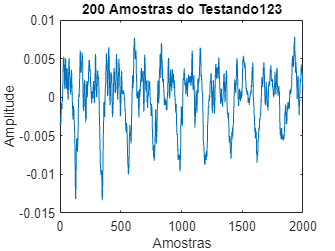

figure
plot(audio2(7001:9000));
title('200 Amostras do Testando123');
xlabel('Amostras');
ylabel('Amplitude');

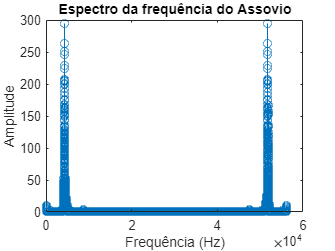

figure

%b)
% Calcular a FFT e o vetor de frequências
X1 = fft(audio1);
X2 = fft(audio2);
N1 = length(audio1);
N2 = length(audio2);
% Plotar o espectro de frequências para o primeiro sinal
stem(abs(X1));
title('Espectro da frequência do Assovio');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

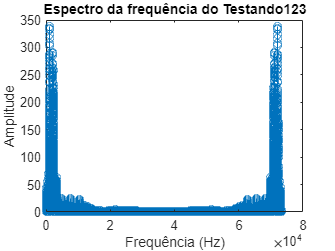

figure
% Plotar o espectro de frequências para o segundo sinal
stem(abs(X2));
title('Espectro da frequência do Testando123');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

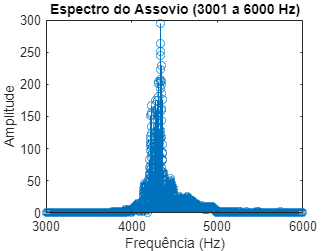

figure

%c) 
% Plotar a amplitude do espectro filtrado para o primeiro sinal (Assovio)
stem(abs(X1));
title('Espectro do Assovio (3001 a 6000 Hz)');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
xlim([3000 6000])

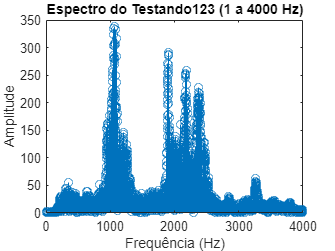

figure;
% Plotar a amplitude do espectro filtrado para o segundo sinal (Teste)
stem(abs(X2));
title('Espectro do Testando123 (1 a 4000 Hz)');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
xlim([0 4000])

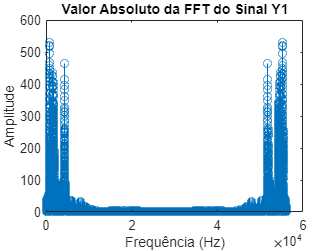

figure;

%d)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%2)
%a)

% Ajustar os tamanhos dos áudios
audio2 = audio2(1:N1);
y1 = audio1 + audio2;
% Normalizar o sinal resultante para evitar distorção
y1 = y1 / max(abs(y1), [], 'all');
% Salvar o sinal em um arquivo WAV
audiowrite('y1.wav', y1, samplerate);

%b)
% Calcular a FFT do sinal y1
Y1 = fft(y1);
% Calcular o vetor de frequências correspondente à FFT
N3 = length(Y1);
% Plotar o valor absoluto da FFT do sinal y1
stem(abs(Y1));
title('Valor Absoluto da FFT do Sinal Y1');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

figure;


%c) 
stem(X1);

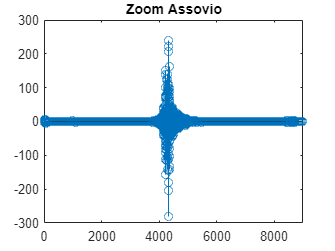

title('Zoom Assovio');
xlim([0 9000])

figure;
stem(X2);

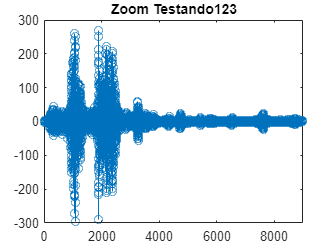

title('Zoom Testando123');
xlim([0 9000])

figure;
stem(Y1);

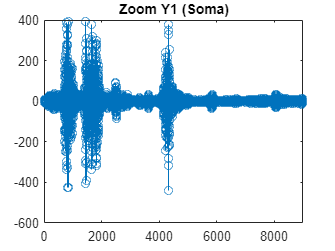

title('Zoom Y1 (Soma)');
xlim([0 9000])

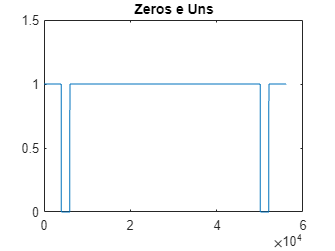

figure;

%assovio entre 5000 e 7000
F = zeros(56100,1);
F(1:3999) = 1;
F(6001:50099) = 1;
F(52099:56100) = 1;
Y2 = Y1.*F;
plot(abs(F))
ylim([0 1.5])
title("Zeros e Uns")

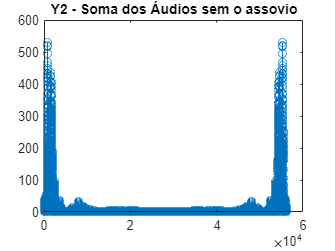

figure
stem(abs(Y2))
title("Y2 - Soma dos Áudios sem o assovio")

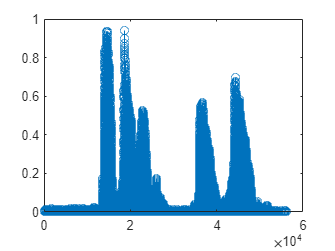

y2 = abs(ifft(Y2));
stem(abs(y2))

sound(y2, samplerate)
%audiowrite('y2.wav', y2, samplerate);




